assert(endsWith(pwd, "non-ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)
Coil.z            = 5.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.01 seconds


clear disk r z

Model.conductivity = 1.91e7 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

build governing equation took 21.88 seconds


#### Solve in time domain

V_E = 1; % (V)
pulse_width = 3e-3; % (s)
Coil.time_domain.voltage = @(t) V_E * (t <= pulse_width);
clear V_E pulse_width

% I_E = 1; % (A)
% f = 2000; % (Hz)
% omega = 2*pi*f;
% Coil.time_domain.current      = @(t) I_E * sin(omega * t);
% Coil.time_domain.current_diff = @(t) I_E * omega * cos(omega * t);
% clear I_E f omega

Coil.time_domain.time_span = [0, 6e-3]; % (s)
[Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in time domain took 2.92 seconds


#### Plot result

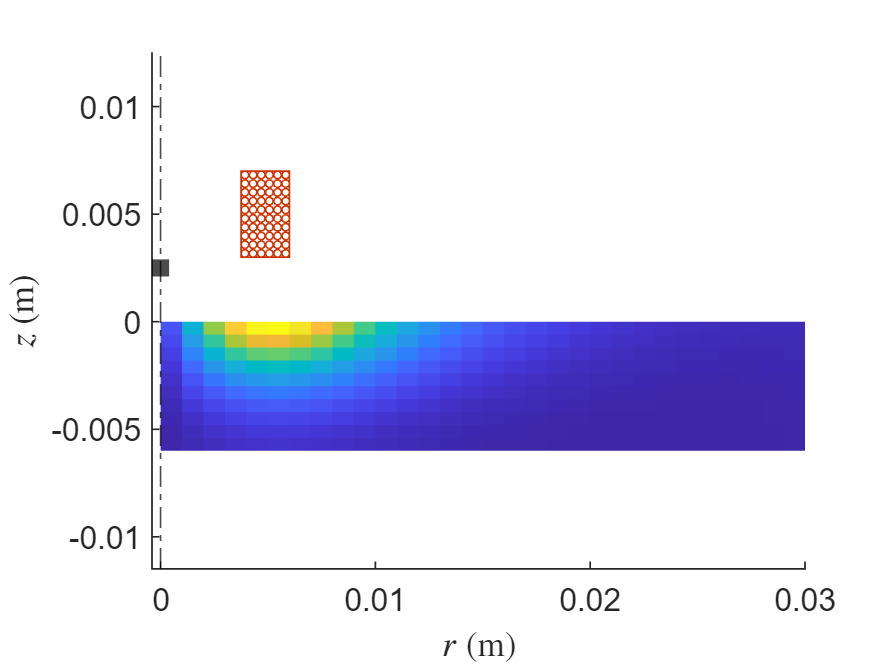

t = 0.1e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
PlotWorld2D(Model, Coil, Sensor, abs(Model.time_domain.J(:,:,k)) );

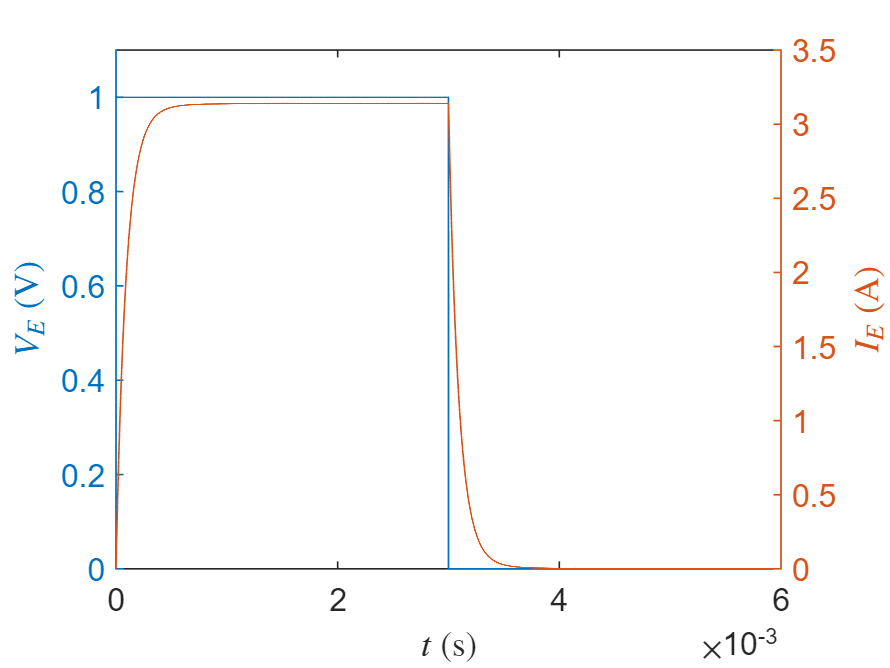

clf
clear t k


if isfield(Coil.time_domain, 'current')
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I_E));
xlabel('$t$ (s)', 'Interpreter','latex')
ylabel('$I_E$ (V)', 'Interpreter','latex')
clf
end

if isfield(Coil.time_domain, 'voltage')
V = Coil.time_domain.voltage(Sensor.time_domain.t);
yyaxis left
plot(Sensor.time_domain.t, V)
ylim([-inf, max(V)*1.1])
ylabel('$V_E$ (V)', 'Interpreter','latex')
yyaxis right
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I_E));
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')
clf
clear V
end

## Compare with FEA

#### Magnetic flux density

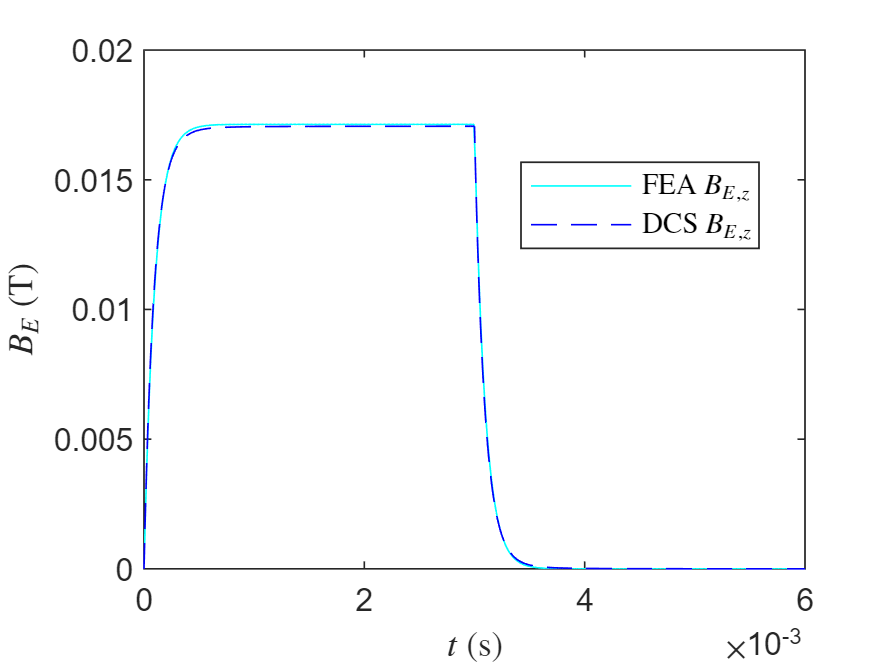

data = readmatrix('FEA_data/B_E.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.t = data(1,:);
FEA.B_E_r = data(2,:);
FEA.B_E_z = data(3,:);
data = readmatrix('FEA_data/B_Mo.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.B_C_r = data(2,:) - FEA.B_E_r;
FEA.B_C_z = data(3,:) - FEA.B_E_z;

plot(FEA.t, FEA.B_E_z, 'c-', 'DisplayName','FEA $B_{E,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(2,1,:)), 'b--', 'DisplayName','DCS $B_{E,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

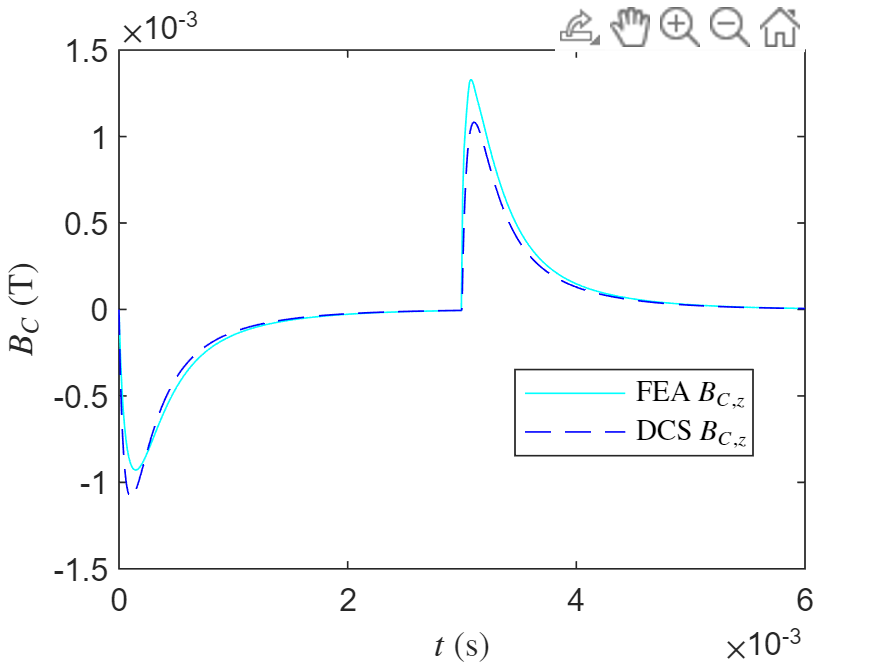

clf

plot(FEA.t, FEA.B_C_z, 'c-', 'DisplayName','FEA $B_{C,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), 'b--', 'DisplayName','DCS $B_{C,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

FEA_B_C_z = FEA.B_C_z;
DCS_B_C_z = interp1(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), FEA.t);
[error, i] = maxk(abs(DCS_B_C_z - FEA_B_C_z), 100);
relative_error = mean(abs(error ./ FEA_B_C_z(i)));
fprintf('average relative error: %e\n', relative_error);

average relative error: 1.601924e-01



clear data FEA_B_C_z DCS_B_C_z relative_error error i

## Material Sweep

#### Solve in time domain

materials      = ["Ti"    "Zn"   "Mo"   "Al"   "Cu"  ];
conductivities = [0.238e7 1.69e7 1.91e7 3.57e7 5.96e7];
colors         = ['r'     'g'    'b'    'k'    'y'   ];

hold on
for i = 1:numel(materials)
    Model.conductivity = conductivities(i) * ones(1,Model.num_elms);
    GoverningEquation = BuildGoveringEquation2D(GoverningEquation, Model);

    [Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

    plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B(2,1,:)), '-', 'DisplayName',materials(i), 'Color',colors(i));
end

solve in time domain took 19.25 seconds
solve in time domain took 2.73 seconds
solve in time domain took 2.49 seconds
solve in time domain took 1.63 seconds
solve in time domain took 0.79 seconds


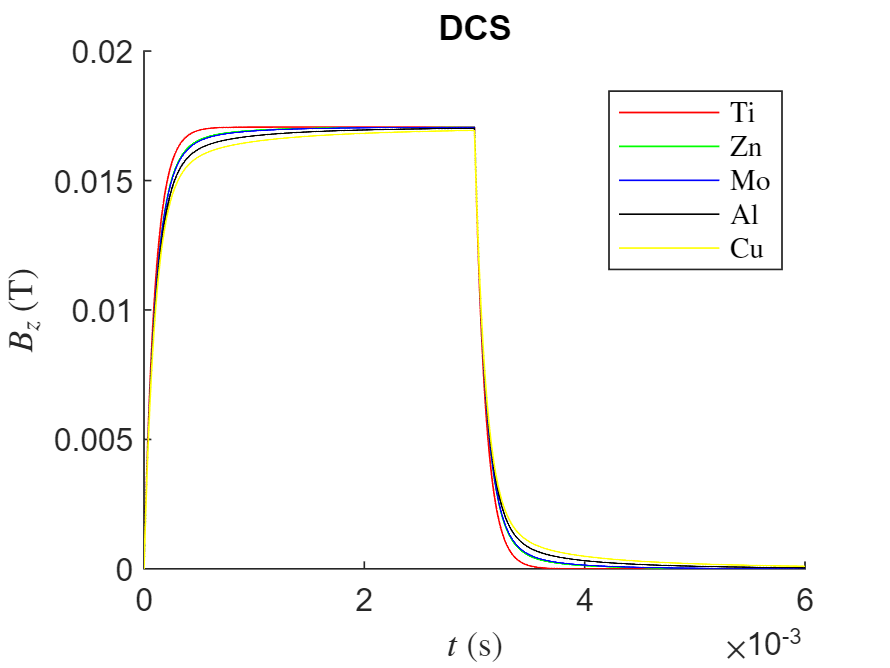

title('DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

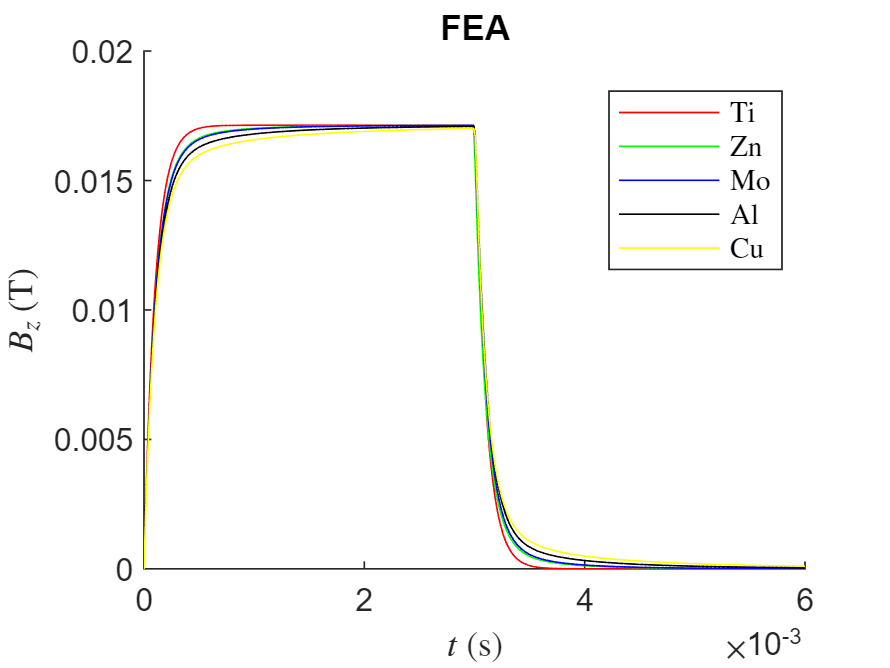

clf

hold on
for i = 1:numel(materials)
    data = readmatrix(sprintf('FEA_data/B_%s.csv',materials(i)), 'CommentStyle','%');
    data = reshape(data(3:end), 3, []);

    plot(data(1,:), data(3,:), '-', 'DisplayName',materials(i), 'Color',colors(i));
end
title('FEA')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

clf

clear materials conductivities colors i data